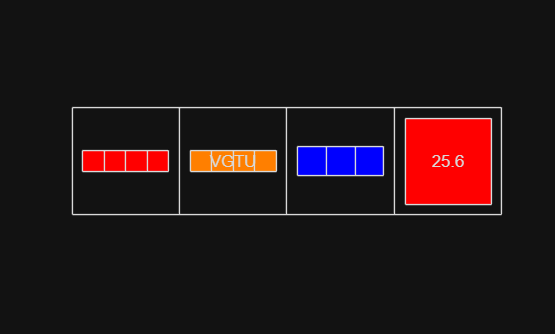

%%Seymur Mammadov
%Ekfu 25/1
%VGTU Computer Engineering student



%% task 1
format compact
C = cell(1, 4);
C{1} = [10 20 30 40];
C{2} = 'VGTU';
C{3} = [true false true];
C{4} = 25.6;

cellplot(C);


lengths = cellfun(@length, C);
empty_status = cellfun(@isempty, C);
real_status = cellfun(@isreal, C);

disp('Length of each cell element:');

Length of each cell element:


disp(lengths);

     4     4     3     1


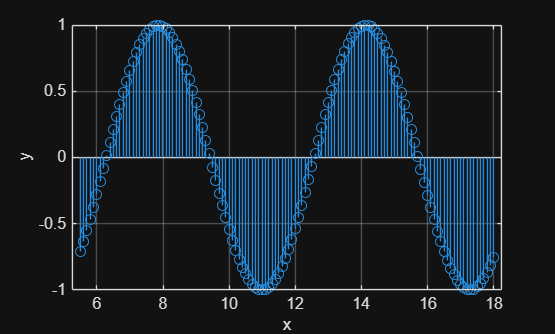


matrix_data = cell2mat(C([1, 4]));


%task 2






format compact
m = input('Enter starting value m: ');
choice = input('Select function (1 for sin, 2 for cos): ');

for k = 1:15
    x = m : 0.1 : (m + 4*pi);

    if choice == 1
        y = sin(x);
    else
        y = cos(x);
    end

    stem(x, y);
    xlabel('x');
    ylabel('y');
    grid on;
    drawnow;

    m = m + pi/8;
    pause(0.5);
end


%task 3

format compact
sentence = input('Enter a sentence: ', 's');
symbol = input('Enter the symbol to remove: ', 's');

clean_sentence = '';
removed_count = 0;

for i = 1:length(sentence)
    if sentence(i) == symbol
        removed_count = removed_count + 1;
    else
        clean_sentence = [clean_sentence, sentence(i)];
    end
end

disp(['Modified sentence: ', clean_sentence]);

Modified sentence: Vilnius   Teh   Computer   Engineering


disp(['Number of removed symbols: ', num2str(removed_count)]);

Number of removed symbols: 1
